%%%% HW 2

## Problem 12c - w/ new Type III BC + RMS Error

Engs105, W24 - Prof. Paulsen

### Numerical Solution

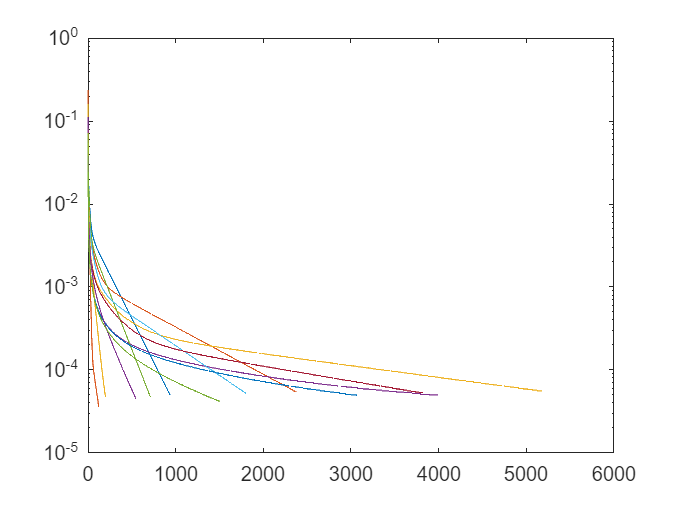

clear; close all
% Parameters
a = 0.1;
R = 1;
th_final = pi/2;

ARange = [0, 1, 100];
NRange = [10, 20, 40, 100];

for jj = [1:length(ARange)]
    for ii = [1:length(NRange)]
    
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        A = ARange(jj);
        N = NRange(ii);
       
        % Ranges for independent variables
        r_range = linspace(a, R, N);
        th_range = linspace(0, th_final, N);
        r_mesh = repmat(r_range, N, 1);
        th_mesh = repmat(th_range', 1, N);
        x_coor = r_mesh .* cos(th_mesh);
        y_coor = r_mesh .* sin(th_mesh);
        filename = ['N' num2str(N) '_A' num2str(A) '_RMS_jacobi.txt'];
        semilogy(readmatrix(filename));
    end
end

for jj = [1:length(ARange)]
    for ii = [1:length(NRange)]
    
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        A = ARange(jj);
        N = NRange(ii);
       
        title_str = ['N = ' num2str(N) ', A = ' num2str(A)];
        
        plot( jacobiRMS((ii-1)*4+jj) )
    end
end